clear;
close all;

addpath('./DCS_functions')

## Electromagnet

EM.num = 1;
EM.ai = 3.75e-3; % inner radius (m)
EM.ao = 6.00e-3; % outer radius (m)
EM.l  = 4.00e-3; % length (m)

EM.Nturns = 60 * ones(1,EM.num);

EM_pos = [0, 0, 6.5e-3]; % (m)
EM = SetPositionRotation(EM, EM_pos, [1,0,0], deg2rad(60));

EM.current_density = 4.276e6; % (A/m^2) todo: calculate from current and geometry

## Sensor

Sensor.num = 2;
Sensor.side_length_z = 0.4e-3;
Sensor.side_length_xy = 0.8e-3;

Sensor_pos1 = EM_pos + [6e-3 0 -2e-3];
Sensor_pos2 = EM_pos + [-6e-3 0 -2e-3];
Sensor = SetPositionRotation(Sensor, [Sensor_pos1;Sensor_pos2], [1,0,0;1,0,0], [0;0]);
clear EM_pos Sensor_pos1 Sensor_pos2

## Model

Model = struct;

vertex_file = 'Square_36mm_g6mm_node.inp';
element_file = 'Square_36mm_g6mm_element.inp';
Model = LoadHexMesh(Model, vertex_file, element_file, 1e-3);
clear vertex_file element_file

Model.conductivity = 2.38e6 * ones(1,Model.num_elms); % (S/m)

PlotWorld(EM, Sensor, Model);

## Governing Equation

GE = BuildGoveringEquation(EM, Model);

## Solve in Frequency Domain

omega = 2*pi * 20000; % (rad/s)
Sol = SolveFrequency(GE, omega);


Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.


Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



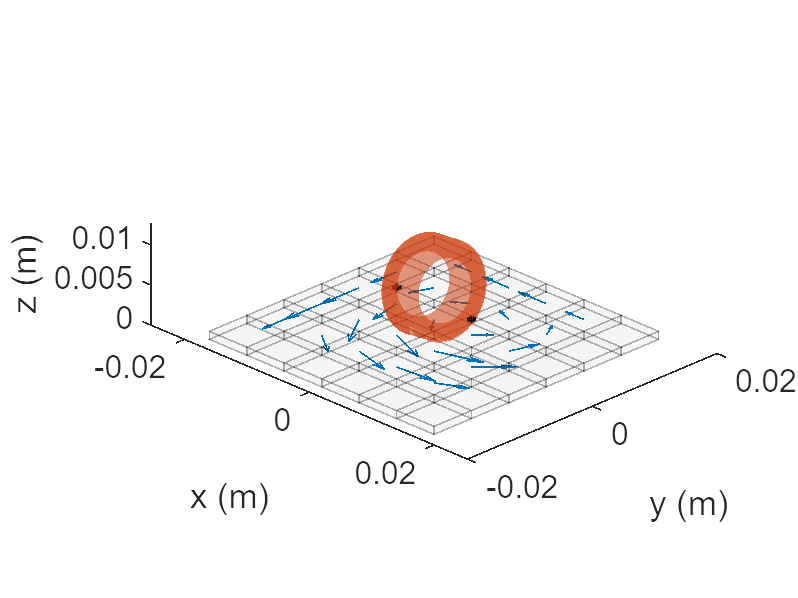


pos = Model.elms_center;
vec = Sol.J_Re;
hold on;
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));